# Apuntes de Clase - Estimadores

Herramientas Matemáticas para el Manejo de la Información

Sesión 12 - 4 de mayo de 2024

# Estimadores

Un estimador $\hat \theta$ es una función de la muestra, o estadístico, que permite estimar un parámetro $\theta$ de la población. Por ejemplo, considérese la variable aleatoria $X$:


$$X:\Omega \to \mathbb{R}$$


La esperanza matemática de la variable aleatoria $X$:


$$E[X] = \mu_X$$


se puede estimar con la media aritmética $\bar X$, o media muestral:


$$\bar{X}:\Omega \to \mathbb{R}$$



$$\bar X = \frac{1}{n}\sum_{i=1}^{n}{x_i}$$


Siendo los $x_i$, con $i=\{1,2,3,\dots,n\}$, los valores de la muestra de tamaño $n$.

Otros ejemplos de interés son: probabilidad, media y desviación estándar, que se pueden estimar de una muestra, por medio de: la frecuencia relativa, media muestral y desviación muestral, respectivamente:


$$\begin{array}{cc}
\text{Parámetro} & \text{Estimador}\\
\theta & \hat \theta \\
P & F_r \\
\mu_X=E[X] & \bar X \\
\sigma_X & S_X
\end{array}$$


Los estimadores son variables aleatorias y por lo tanto, tienen asociada una distribución de probabilidad.


$$\hat\theta: \Omega \to \mathbb{R}$$



$$\hat \theta \sim \text{CDF}$$


# Algunas propiedades de los estimadores

Los estimadores se pueden comparar revisando, entre otras, las siguientes propiedades: sesgo, eficiencia, consistencia y robustez.

## **Sin sesgo**

Un estimador $\hat \theta$ del parámetro $\theta$ no tiene sesgo si:


$$E\left[\hat \theta\right]= \theta$$


## Eficiencia

Un estimador $\hat \theta_1$ es más eficiente que el estimador $\hat \theta_2$ si:


$$\sigma_{\hat\theta_1}<\sigma_{\hat\theta_2}$$


## Consistencia

Un estimador es consistente si la secuencia de estimadores **converge en probabilidad** al parámetro que se desea estimar.


$$\hat{\theta_n} \overset{p}{\to}  \theta$$


#### Convergencia en probabilidad

Sea $X_1, X_2, \dots$ una secuencia de variables aleatorias (no necesariamente independientes) y sea $\theta$ un número real. Se dice que la secuencia $X_n$ converge en probabilidad a $\theta$, si para cada $\epsilon > 0$:


$$\lim_{n\to \infty} P[\vert X_n-\theta\vert\geq \epsilon]=0$$


## Robustez

Un estimador es robusto si el desempeño del mismo no se afecta, en mayor medida, cuando varía la distribución de la muestra. En otras palabras, un estimador robusto permitiría estimar el parámetro para una gama amplia de distribuciones de la muestra. 

# Estimador de la Media

Evalúe cuál de los siguientes estimadores es el más adecuado para estimar la media de una muestra de tamaño *n*.


$$\begin{array}{ccc}
\textbf{Estimador} & \hat\theta & \textbf{Función de MATLAB}\\
\text{Media Muestral} &
\frac{1}{n}\sum_{i=1}^{n}{x_i} & \texttt{mean, mean2} \\
\text{Mediana Muestral} & ? & \texttt{median}\\
\text{Rango Medio} & \frac{\max\{\mathbf{x}\}+\min\{\mathbf{x}\}}{2} & \texttt{(max(x)+min(x))/2}
\end{array}$$


Siendo los $x_i$, con $i=\{1,2,3,\dots,n\}$, los valores de la muestra de tamaño $n$. Esto es, $\mathbf{x} = \{x_1, x_2, \dots, x_n\}$.

## Estrategia a seguir

Para determinar cuál de los estimadores es el más adecuado, se procederá a generar muestras normalmente distribuídas de tamaño fijo $n = \{2, 3, 4, \cdots\}$. Luego, a cada muestra se le aplicará uno de los estimadores propuestos, para obtener así un conjunto de estimaciones puntuales. Finalmente, al conjunto de estimaciones puntuales se le estimará la función de densidad de probabilidad que permitirá evaluar las propiedades del estimador bajo estudio. A continuación se codifica dicha estrategia:

n = 2; % Tamaño de la muestra
repeticiones = 100000;
mediamuestral = zeros(1,repeticiones);
tic;
for i = 1:repeticiones
    muestras = randn(1,n); % Normal estándar
    mediamuestral(i) = mean(muestras);
end
toc;

Elapsed time is 0.117463 seconds.


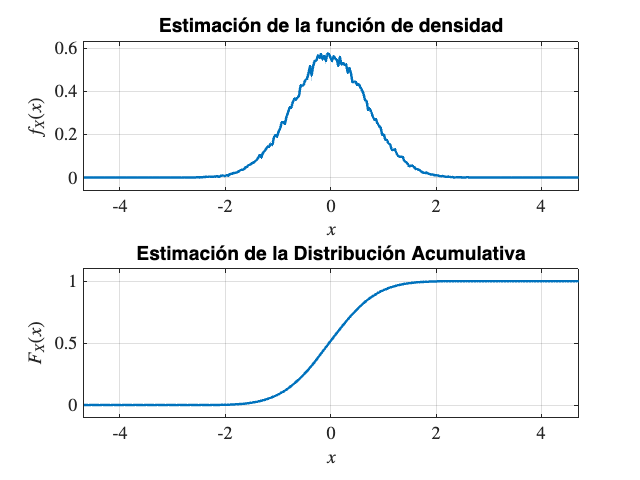

figure(1);
pdfcdfcontinua(mediamuestral);

## Ejercicio en clase

Proponga una solución equivalente, que no utilice ciclos (for, parfor, while, etc). Vectorice la solución.

## Estudiantes que resolvieron el ejercicio

Jhonatan González

Karen Núñez

## Estrategia vectorizada

El resultado anterior es útil pero computacionalmente ineficiente. Por eso, a continuación se propone una solución vectorizada :

n = 2; % Tamaño de la Muestra
repeticiones = 100000;
tic;
muestras = mean(randn(n,repeticiones));
toc;

Elapsed time is 0.006760 seconds.


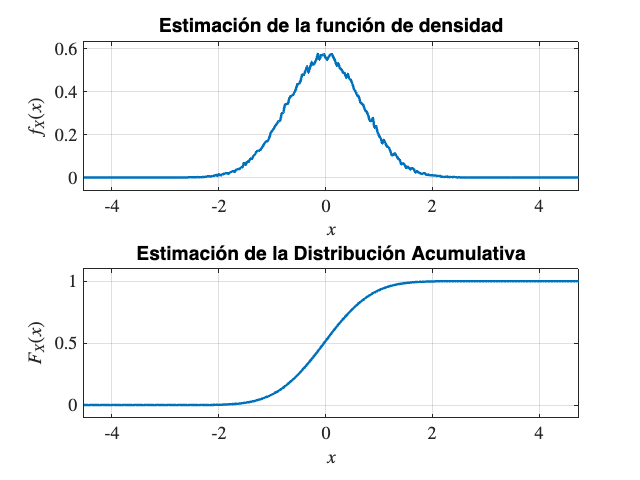

figure(2);
pdfcdfcontinua(muestras);

# Estimador 1: media muestral

La media muestral, o media aritmética, es el estimador definido por:


$$\overline{X} = \frac{\sum_{i=1}^{n}x_i}{n}$$


## Prueba de Sesgo

n = 56; %Tamaño de la muestra
repeticiones = 100000;

tic;
muestra = randn(n,repeticiones);
estimaciones = mean(muestra);
toc;

Elapsed time is 0.107342 seconds.


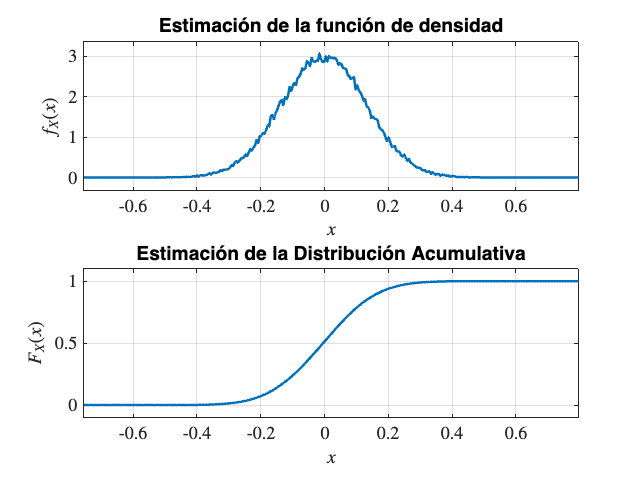

figure(3);
pdfcdfcontinua(estimaciones);

## Prueba de Consistencia

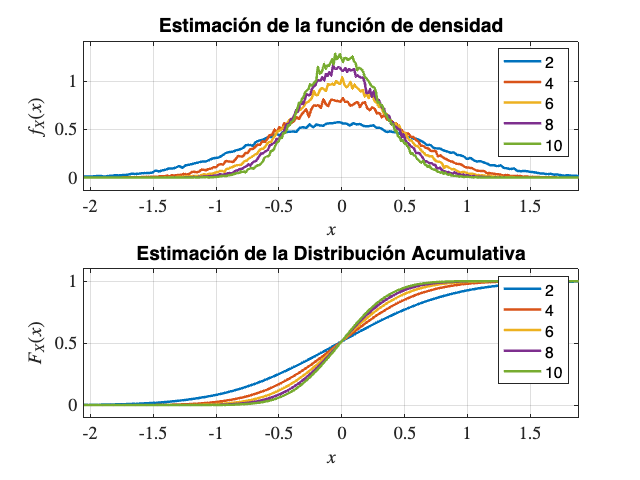

numerodemuestras = 2:2:10;
figure(3);
for n = numerodemuestras
    muestra = randn(n,repeticiones);
    estimaciones = mean(muestra);
    pdfcdfcontinua(estimaciones);
    subplot(2,1,1);
    hold on;
    subplot(2,1,2);
    hold on;
end
subplot(2,1,1);
legend(string(numerodemuestras));
hold off;
subplot(2,1,2);
legend(string(numerodemuestras));
hold off;

## Prueba de Robustez

n = 50;
repeticiones = 100000;
figure(4);

Datos normalmente distribuidos con $\mu = 0.5$

muestra = 0.5 + randn(n,repeticiones);
estimaciones = mean(muestra);
pdfcdfcontinua(estimaciones);
subplot(2,1,1);
hold on;
subplot(2,1,2);
hold on;

Datos uniformemente distribuidos 

muestra = rand(n,repeticiones);
estimaciones = mean(muestra);
pdfcdfcontinua(estimaciones);

Datos exponencialmente distribuidos

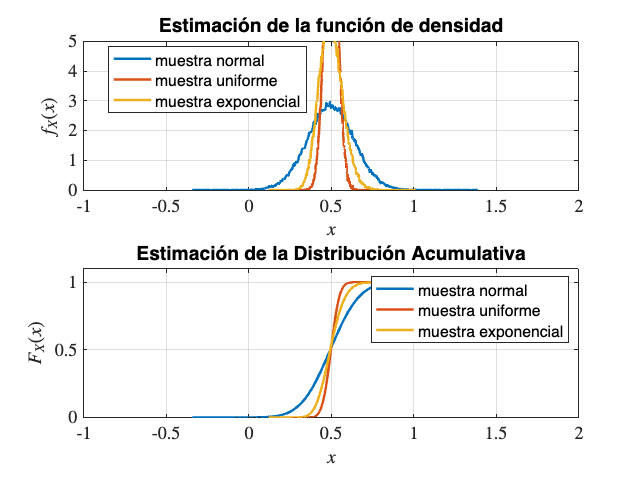

muestra = exprnd(0.5,n,repeticiones);
estimaciones = mean(muestra);
pdfcdfcontinua(estimaciones);
subplot(2,1,1);
legend('muestra normal',...
    'muestra uniforme',...
    'muestra exponencial',...
    'Location',"best");
hold off;
axis([-1,2,0,5]);
subplot(2,1,2);
legend('muestra normal',...
    'muestra uniforme',...
    'muestra exponencial');
hold off;
axis([-1,2,0,1.1]);

# Estimador 2: mediana muestral

La mediana muestral es el estimador definido por:


$$M_X=\begin{cases}
x_{(n+1)/2}, &n \;\text{impar}\\
\frac{x_{n/2}+x_{n/2+1}}{2}, &n \;\text{par}
\end{cases}$$


## Prueba de Sesgo

n = 10; % Tamaño de la Muestra
repeticiones = 100000;

tic;
muestra = randn(n,repeticiones);
estimaciones = median(muestra);
toc;

Elapsed time is 0.060306 seconds.


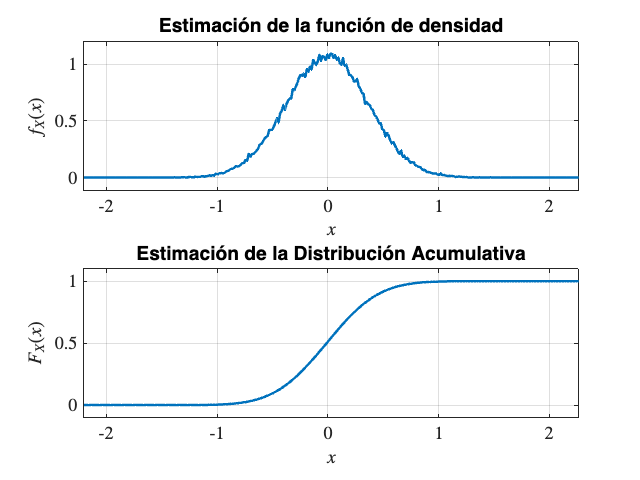

figure(5);
pdfcdfcontinua(estimaciones);

## Prueba de Consistencia

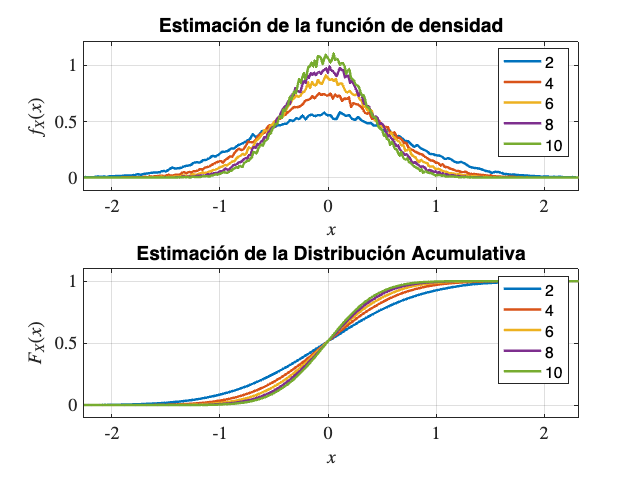

numerodemuestras = 2:2:10;
repeticiones = 100000;
figure(6);

for n = numerodemuestras
    muestra = randn(n,repeticiones);
    estimaciones = median(muestra);
    pdfcdfcontinua(estimaciones);
    subplot(2,1,1);
    hold on;
    subplot(2,1,2);
    hold on;
end
subplot(2,1,1);
legend(string(numerodemuestras));
hold off;
subplot(2,1,2);
legend(string(numerodemuestras));
hold off;

## Prueba de Robustez

n = 50;
repeticiones = 1000000;
figure(7);

Datos normalmente distribuidos con $\mu = 0.5$

muestra = 0.5 + randn(n,repeticiones);
estimaciones = median(muestra);
pdfcdfcontinua(estimaciones);
subplot(2,1,1);
hold on;
subplot(2,1,2);
hold on;

Datos uniformemente distribuidos

muestra = rand(n,repeticiones);
estimaciones = median(muestra);
pdfcdfcontinua(estimaciones);

Datos exponencialmente distribuidos

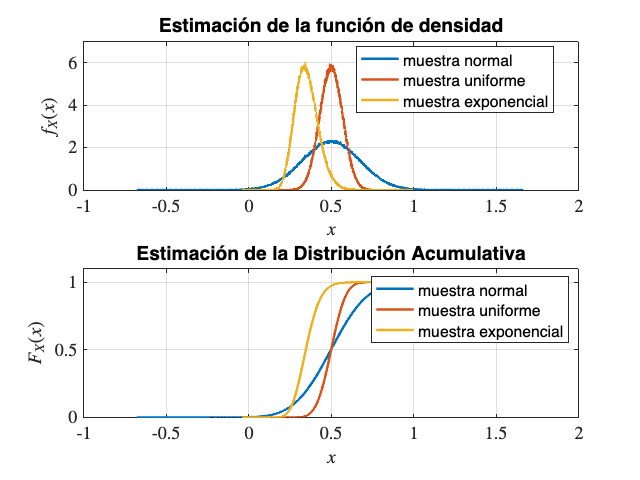

muestra = exprnd(0.5,n,repeticiones);
estimaciones = median(muestra);
pdfcdfcontinua(estimaciones);
subplot(2,1,1);
legend('muestra normal',...
    'muestra uniforme',...
    'muestra exponencial',...
    'Location',"best");
hold off;
axis([-1,2,0,7]);
subplot(2,1,2);
legend('muestra normal',...
    'muestra uniforme',...
    'muestra exponencial');
hold off;
axis([-1,2,0,1.1]);

# Estimador 3: rango medio

Defínase el estimador rango medio con la siguiente expresión:


$$R_X=\frac{\max(x_i)+\min(x_i)}{2}$$


La implementación del estimador $R_X$ se realiza al final de este documento, con la función `rangomedio`.

## Prueba de Sesgo

n = 20; % Tamaño de la Muestra
repeticiones = 100000;

tic;
muestra = randn(n,repeticiones);
estimaciones = rangomedio(muestra);
toc;

Elapsed time is 0.088796 seconds.


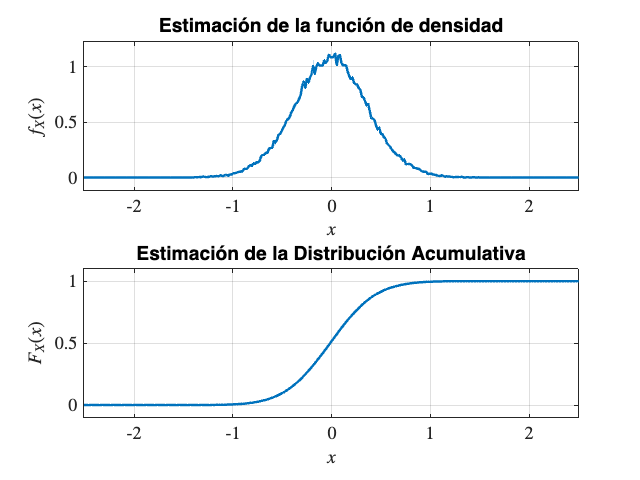

figure(8);
pdfcdfcontinua(estimaciones);

## Prueba de Consistencia

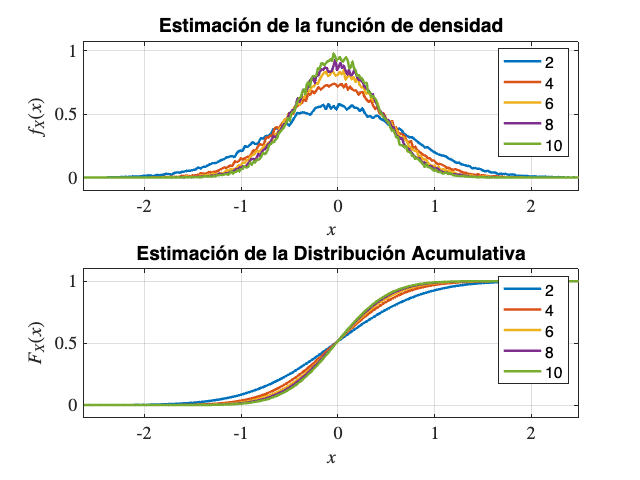

numerodemuestras = 2:2:10;
repeticiones = 100000;
figure(9);

for n = numerodemuestras
    muestra = randn(n,repeticiones);
    estimaciones = rangomedio(muestra);
    pdfcdfcontinua(estimaciones);
    subplot(2,1,1);
    hold on;
    subplot(2,1,2);
    hold on;
end
subplot(2,1,1);
legend(string(numerodemuestras));
hold off;
subplot(2,1,2);
legend(string(numerodemuestras));
hold off;

## Prueba de Robustez

n = 50;
repeticiones = 100000;
figure(10);

Datos normalmente distribuidos con $\mu = 0.5$

muestra = 0.5 + randn(n,repeticiones);
estimaciones = rangomedio(muestra);
pdfcdfcontinua(estimaciones);
subplot(2,1,1);
hold on;
subplot(2,1,2);
hold on;

Datos uniformemente distribuidos

muestra = rand(n,repeticiones);
estimaciones = rangomedio(muestra);
pdfcdfcontinua(estimaciones);

Datos exponencialmente distribuidos con $\lambda =2$

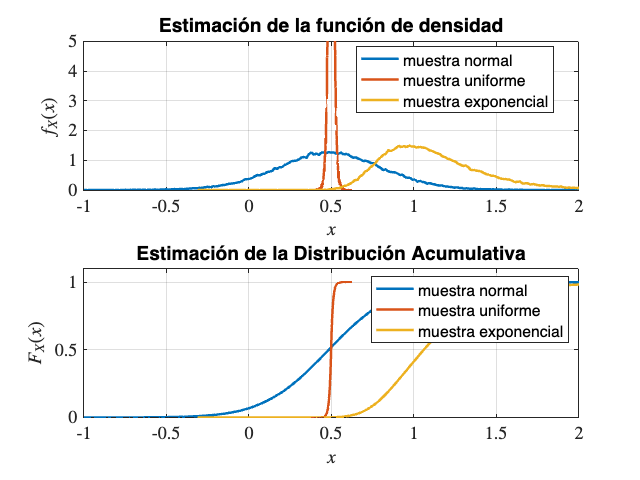

lambda = 2; % para que la media sea de 0.5
muestra = exprnd(1/lambda,n,repeticiones);
estimaciones = rangomedio(muestra);
pdfcdfcontinua(estimaciones);
subplot(2,1,1);
legend('muestra normal',...
    'muestra uniforme',...
    'muestra exponencial',...
    'Location',"best");
hold off;
axis([-1,2,0,5]);
subplot(2,1,2);
legend('muestra normal',...
    'muestra uniforme',...
    'muestra exponencial');
hold off;
axis([-1,2,0,1.1]);

# Estimador más eficiente

Para determinar cuál de los tres estimadores estudiados es el más eficiente, se propone obtener las distribuciones respectivas y comparar las desviaciones estándar.

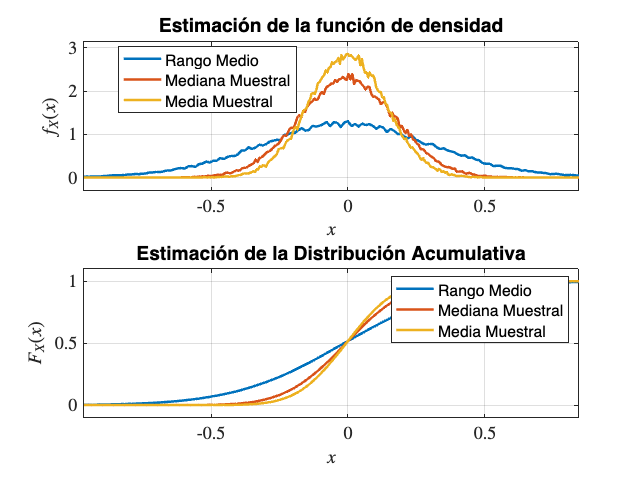

n = 50;
repeticiones = 100000;
figure(11);

muestra = randn(n,repeticiones);
estimaciones = rangomedio(muestra);
pdfcdfcontinua(estimaciones);
subplot(2,1,1);
hold on;
subplot(2,1,2);
hold on;
estimaciones = median(muestra);
pdfcdfcontinua(estimaciones);
estimaciones = mean(muestra);
pdfcdfcontinua(estimaciones);
subplot(2,1,1);
hold off;
legend('Rango Medio',...
    'Mediana Muestral',...
    'Media Muestral',...
    'Location',"best");
subplot(2,1,2);
hold off;
legend('Rango Medio',...
    'Mediana Muestral',...
    'Media Muestral');

# Tarea 14

Diseñe y codifique una función en MATLAB, llamada `codificarnd(datos,nombre)` que se encargue de codificar una función de MATLAB llamada `nombre(n,m)`. La función codificada, debe generar números aleatorios con la misma distribución muestral de los datos de entrada.

## Parámetros de Entrada de `codificarnd`

`datos`: una matriz que contiene los resultados de un experimento aleatorio. Los elementos de la matriz deben ser números reales.

`nombre`: es el nombre de la función y en consecuencia, el del archivo de salida.

## Parámetros de Entrada que debe considerar la función codificada

`m`: número de filas.

`n`: número de columnas.

## Ejemplo

Considérese que se dispone de los datos del acelerómetro en la variable `aceleracionz` y que se desea obtener una función que genere matrices con números aleatorios. Los elementos de las matrices generadas deben presentar la misma distribución muestral de los datos indicados en `aceleracionz`. Se propone escoger como nombre de la función a `acelrnd`. Para generar la función indicada se debe ejecutar:

load('datosacelerometro.mat'); %Carga la variable aceleraciónz
codificarnd(aceleracionz,'acelrnd');

acelrnd.m codificado. Revisa tu carpeta de MATLAB.
Luego puedes ejecutar: acelrnd(m,n).


El resultado esperado es un archivo llamado acelrnd.m. Ahora bien, para obtener una muestra de tamaño 3x2, debe ser suficiente con ejecutar:

acelrnd(3,2)

ans =     9.8196    9.8196
    9.8028    9.8051
    9.7908    9.8360


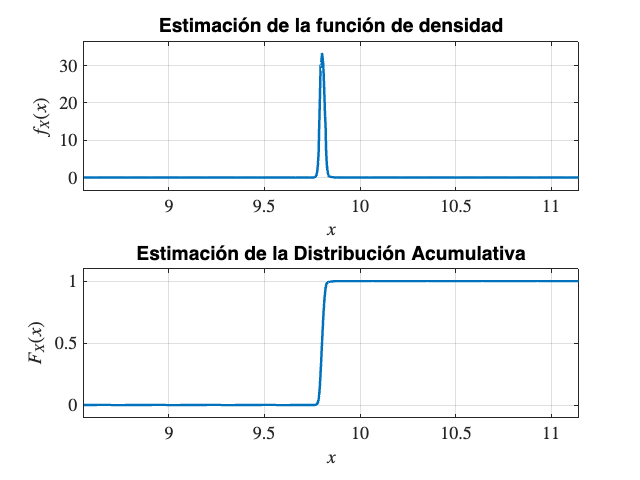

figure(12);
pdfcdfcontinua(acelrnd(1,1000000));

Nota: se adjunta el archivo `datosacelerometro.mat` y un ejemplo de la función `acelrnd.`

# Funciones

Función del estimador 3: rango medio

function y = rangomedio(muestra)
    y = (max(muestra)+min(muestra))/2;
end

Función para la tarea:

function [] = codificarnd(datos,nombre)
    % aquí debe ir el código de la tarea 14
    disp([nombre,'.m codificado. Revisa tu carpeta de MATLAB.']);
    disp(['Luego puedes ejecutar: ',nombre,'(m,n).']);   
end